# **Homework I**

**Miguel Gonzalez and Mario Hernandez**

clc; clear; 

**Exercise 1**

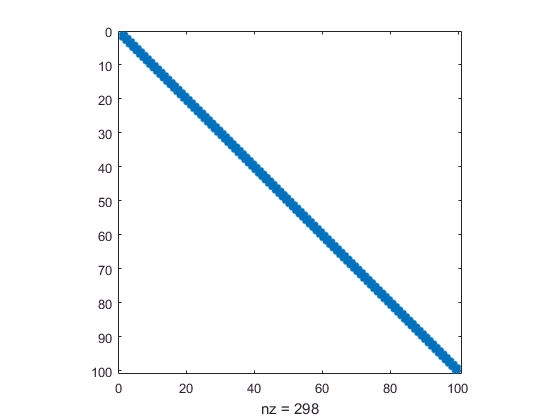

clear
addpath('iterative', 'direct_solve', 'gradient_descent', 'plots_graphs', 'tridiag');
problem = load('heatI.mat', 'A', 'b');
%problemII = load('heatII.mat', 'A', 'b');
A = problem.A; b = problem.b;
%AII = problemII.A; bII = problemII.b;
n = length(b);
parameters.tol = 1e-8;
parameters.maxiter = 10000000;
parameters.print = 0;
parameters.step_iter = 1000;
iter = zeros(8, 1);
iter_op = zeros(8, 1);

spy(A);

bandI = bandwidth(A); % With that, we know that the matrix is tridiagonal
fprintf('The bandwidth of A is: %d', bandI);

The bandwidth of A is: 1

fprintf('The condition number of A is: %d', condest(A));

The condition number of A is: 5.100000e+03

We can expect a slow convergence, since the conditional number is very large. Also, we know that the matrix is tridiagonal.

**Exercise 2**

tic
LU = LUfactor(A);
x1 = LUsolve(LU, b);
toc

Elapsed time is 0.126722 seconds.


r1 = b - A*x1;
r1n = norm(r1);
tic
x2 = A\b;
toc

Elapsed time is 0.019829 seconds.


The MATLAB direct method is the faster since it is optimized and calls BLAS subroutines. That is because there are languages that are compilled, and those who are interpreted. MATLAB is an interpreted one, but the direct method is using libraries with functions from compilled languages (such as C/C++ or Fortran).

**Exercise 3**

tic
x3 = zeros(n, 1);
[x3, iter(3), Jacobi_iter, Jacobi_err] = iterate('jacobi', A, b, x3, parameters);
toc

Elapsed time is 0.340478 seconds.



tic
x4 = zeros(n, 1);
[x4, iter(4), Gaussseidel_iter, Gaussseidel_err] = ...
    iterate('gaussseidel', A, b, x4, parameters);
toc

Elapsed time is 9.341695 seconds.



fprintf('Iterations in Jacobi: %d \n', iter(3));

Iterations in Jacobi: 37150 


fprintf('Iterations in Gauss-Seidel: %d \n', iter(4));

Iterations in Gauss-Seidel: 18585 


It is interesting to see that, even though iterations of the Gauss-Seidel method are less, the Jacobi is faster. This is because we have used Jacobi in the vectorial form (explicit vectorization), and that is  faster than the loop in Gauss-Seidel, again due to the same, the kind of language that MATLAB is. An example to see this, is that doing a dot product, the result using a for loop or the direct operation is the same. The direct operation is faster even if at the lower level it is also doing a loop, since the for loop is slower in MATLAB than in other languages.

**Exercise 4**

tic
x5 = zeros(n, 1);
parameters.omega = 1.94; % We found that value by optimizing beforehand
[x5, iter(5), SOR_iter, SOR_err] = iterate('sor', A, b, x5, parameters);
toc

Elapsed time is 0.279098 seconds.


fprintf('Iterations in SOR: %d \n', iter(5))

Iterations in SOR: 362 


We can see that by using a properly optimized value for omega, the convergence of SOR is very competitive with other methods.

**Exercise 5**

tic
x6 = zeros(n, 1);
[x6, iter(6), Descent_iter, Descent_err] = descent(A, b, x6, parameters);
toc

Elapsed time is 0.525343 seconds.



tic
x7 = zeros(n, 1);
[x7, iter(7), CG_iter, CG_err] = cg(A, b, x7, parameters);
toc

Elapsed time is 0.034161 seconds.



tic
x8 = zeros(n, 1);
[x8, iter(8), CG_jacobi_preconditioner_iter, CG_jacobi_preconditioner_err] =...
    cg_jacobi_preconditioner(A, b, x8, parameters);
toc

Elapsed time is 0.038279 seconds.



fprintf('Iterations in Descent Method: %d \n', iter(6));

Iterations in Descent Method: 37322 


fprintf('Iterations in Conjugate Gradient Method: %d \n', iter(7));

Iterations in Conjugate Gradient Method: 100 


fprintf('Iterations in CG with Jacobi preconditioner: %d \n', iter(8));

Iterations in CG with Jacobi preconditioner: 100 


The descent method is converging very fast, but the conjugate gradient method is even faster. CG will always converge in n iteration or less, ignoring numerical erros. We also can see that the preconditioner is not accelerating the method. That is because the diagonal of the matrix is the same value, and at the end of the day, what is doing that preconditioner is only scaling the matrix A and vector b, so the convergence is the same and it has to compute more operations in order to get the inverse.

**Exercise 6**

We will only display results for matrix heatI. These results can be extended to heatII, but considering the cost of naive stationary methods being of the order of O($n^2$), we have decided not to. A line in Ex. 1 can be uncommented to use heatII for the calculations.

m = ceil(max(iter)/parameters.step_iter);
Iterations = zeros(1, m);
for i = 1:(m - 1)
    Iterations(1, i) = i*parameters.step_iter;
end
Iterations(1, m) = max(iter);


Jacobi_err_pad = addzeros(Jacobi_err, m);
Gaussseidel_err_pad = addzeros(Gaussseidel_err, m);
SOR_err_pad = addzeros(SOR_err, m);
Descent_err_pad = addzeros(Descent_err, m);
CG_err_pad = addzeros(CG_err, m);
CG_jacobi_preconditioner_err_pad = addzeros(CG_jacobi_preconditioner_err, m);

Iterations = Iterations'; Jacobi_err_pad = Jacobi_err_pad';
Gaussseidel_err_pad = Gaussseidel_err_pad'; SOR_err_pad = SOR_err_pad';
Descent_err_pad = Descent_err_pad'; CG_err_pad = CG_err_pad';
CG_jacobi_preconditioner_err_pad = CG_jacobi_preconditioner_err_pad';

T = table(Iterations, Jacobi_err_pad, Gaussseidel_err_pad, SOR_err_pad,...
    Descent_err_pad, CG_err_pad, CG_jacobi_preconditioner_err_pad,...
    'VariableNames',{'Iteration','Jacobi','GaussSeidel','SOR','GradDescent',...
    'ConjGrad','ConjGradJac'});

T =     Iteration      Jacobi      GaussSeidel       SOR        GradDescent    ConjGrad    ConjGradJac
    _________    __________    ___________    __________    ___________    ________    ___________

     1000           0.40505       0.24529     9.9252e-09       0.52768     3.67e-12    2.3765e-12 
     2000           0.24347      0.093273              0       0.31685            0             0 
     3000           0.14987      0.035445              0        0.1941            0             0 
     4000          0.092374      0.013468              0       0.11903            0             0 
     5000          0.056941     0.0051174              0      0.072997            0             0 
     6000          0.035099     0.0019445              0      0.

disp(T);

    Iteration      Jacobi      GaussSeidel       SOR        GradDescent    ConjGrad    ConjGradJac
    _________    __________    ___________    __________    ___________    ________    ___________

     1000           0.40505       0.24529     9.9252e-09       0.52768     3.67e-12    2.3765e-12 
     2000           0.24347      0.093273              0       0.31685            0             0 
     3000           0.14987      0.035445              0        0.1941            0             0 
     4000          0.092374      0.013468              0       0.11903            0             0 
     5000          0.056941     0.0051174              0      0.072997            0             0 
     6000          0.035099     0.0019445              0      0.0447

We will plot the convergence of the algorithms (residuals vs number of iterations), with one graph containing the "slow" methods (Jacobi, Gauss-Seidel, naive Gradient Descent), and the other covering the "fast" ones (SOR, Conjugate Gradients w/ and w/o preconditioning).

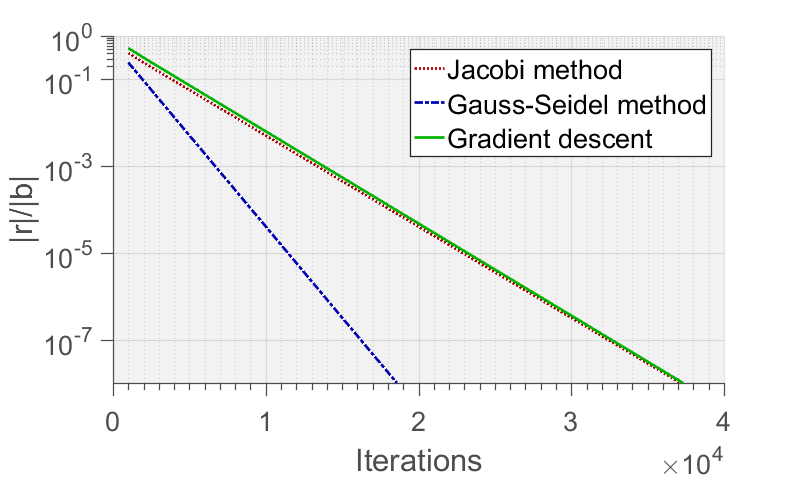

parameters.step_iter = 50;
x5 = zeros(n, 1);
[x5, iter(5), SOR_iter, SOR_err] = iterate('sor', A, b, x5, parameters);
x7 = zeros(n, 1);
[x7, iter(7), CG_iter, CG_err] = cg(A, b, x7, parameters);
x8 = zeros(n, 1);
[x8, iter(8), CG_jacobi_preconditioner_iter, CG_jacobi_preconditioner_err] =...
    cg_jacobi_preconditioner(A, b, x8, parameters);

plot_semilog_1;

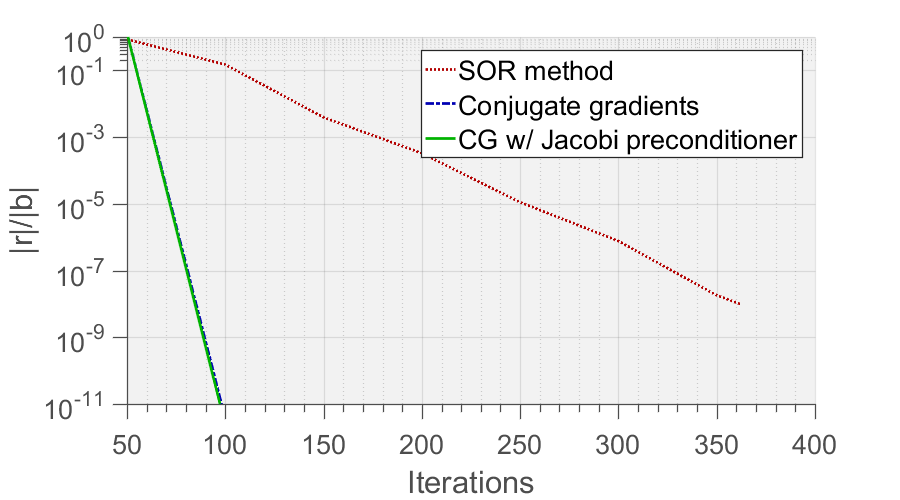

plot_semilog_2;

It should be noted that, while naive gradient descent seems comparable to Jacobi's method, it is theoretically capable of quadratic convergence for well-behaved functions. Unfortunately, the quadratic form of A has the form of a "narrow valley", preventing GD from achieving quadratic convergence.

Also of importance is the fact that the Jacobi preconditioner for applying conjugate gradients on this matrix is not appropriate, since it is just scaling the matrix. This does not modify the condition number, thus the comparable convergence to naive CG.

**Optimized functions for tridiagonal sparse matrices**

tic
LU = trid_LUfactor(A);
y1 = trid_LUsolve(LU, b);
toc

Elapsed time is 0.037045 seconds.


Direct LU factorization and solving benefits a lot from optimization to tridiagonal matrices, since we are avoiding loops iterating through the full triangular matrices.

tic
y3 = zeros(n, 1);
[y3, iter_op(3)] = trid_iterate('jacobi', A, b, y3, parameters);
toc

Elapsed time is 0.605502 seconds.


tic
y4 = zeros(n, 1);
[y4, iter_op(4)] = trid_iterate('gaussseidel', A, b, y4, parameters);
toc

Elapsed time is 10.708718 seconds.



fprintf('Iterations in optimized Jacobi: %d \n', iter_op(3));

Iterations in optimized Jacobi: 37150 


fprintf('Iterations in optimized Gauss-Seidel: %d \n', iter_op(4));

Iterations in optimized Gauss-Seidel: 18585 


Take note that Jacobi's and Gauss-Seidel's methods are pretty much as optimized as it gets without writing explicit loops (a bad practice in MATLAB). We have used sparse primitives to reduce the memory usage, but that introduces a noticeable overhead in memory management.

tic
y5 = zeros(n, 1);
parameters.omega = 1.94;
[y5, iter_op(5)] = trid_iterate('sor', A, b, y5, parameters);
toc

Elapsed time is 0.247257 seconds.


fprintf('Iterations in SOR: %d \n', iter_op(5))

Iterations in SOR: 362 


Same thing for SOR.

tic
x6 = zeros(n, 1);
[x6, iter(6), Descent_iter, Descent_err] = descent(A, b, x6, parameters);
toc

Elapsed time is 0.533651 seconds.



tic
x7 = zeros(n, 1);
[x7, iter(7), CG_iter, CG_err] = cg(A, b, x7, parameters);
toc

Elapsed time is 0.042263 seconds.



tic
x8 = zeros(n, 1);
[x8, iter(8), CG_jacobi_preconditioner_iter, CG_jacobi_preconditioner_err] =...
    cg_jacobi_preconditioner(A, b, x8, parameters);
toc

Elapsed time is 0.070265 seconds.


Finally, for gradient-based methods, the optimizations are purely memory based as well. Introducing loops for matrix products to optimize manually will introduce overhead that offsets the optimization benefits (not to mention that MATLAB's subroutines calling BLAS/LAPACK are already as optimized as they get).